# CBD Final analysis 

The aim of this script is to run the final analysis for the CBD project and paper. 

clear all; close all; clc
% the folder to the data files 
cd('/Volumes/MacBack/GenzelLab/CSD/HPC_32by3601_data')
% the aim of this step is read one data file (example) --> extract the channels
DataChannels        = load('GC_ratID210_veh.mat'); % enter the file name 
% that was my vehicle example GC_ratID210_veh.mat
% the fields name of the sturcture provided 
structure_Name      = fieldnames(DataChannels);
% time vector 
timevect            = linspace(-3,3,3601);
pyramidalChannel    = 8;
HH                  = 'False';
idxS                = 601;
% lopping through different events and structures 
for iStr = 1:size(structure_Name,1)-1
    Events_extr = DataChannels.(structure_Name{iStr});% extract different events
    if iStr == 1
        % we extract the events of complex sharp wave events 
        SingleEvents1                           = Events_extr.waveforms;
        EventsTable1                            = Events_extr.grouped_oscil_table;
%         idx_end1                                = EventsTable1.Six_End;
        idx_end1                                = ones(size(SingleEvents1,1),1)*1800;
        for iSingEvent1 = 1:size(SingleEvents1,1)
            twin1                               = [idx_end1(iSingEvent1)-300 idx_end1(iSingEvent1)+300];
            timevect1                           = linspace(-0.5,0.5,idxS);
            csd_trial_1                         = csd_analysis_cannabis_single(SingleEvents1{iSingEvent1}, timevect1, HH,pyramidalChannel,twin1);
            csd_mat_cSWR(:,:,iSingEvent1)       = csd_trial_1.data;
            lfp1                                = SingleEvents1{iSingEvent1};
            lfp_mat_cSWR(:,:,iSingEvent1)       = lfp1(:,twin1(1):twin1(2));
        end
    end
    if iStr == 2
        % we extract the events of ripple without sharp waves  
        SingleEvents2                           = Events_extr.waveforms;
        EventsTable2                            = Events_extr.grouped_oscil_table;
%         idx_end2                                = EventsTable2.Six_End;
        idx_end2                                = ones(size(SingleEvents2,1),1)*1800;
        for iSingEvent2 = 1:size(SingleEvents2,1)
            twin2                               = [idx_end2(iSingEvent2)-300 idx_end2(iSingEvent2)+300];
            timevect2                           = linspace(-0.5,0.5,idxS);
            csd_trial_2                         = csd_analysis_cannabis_single(SingleEvents2{iSingEvent2}, timevect2, HH,pyramidalChannel,twin2);
            csd_mat_Ripp(:,:,iSingEvent2)       = csd_trial_2.data;
            lfp2                                = SingleEvents2{iSingEvent2};
            lfp_mat_Ripp(:,:,iSingEvent2)       = lfp2(:,twin2(1):twin2(2));
        end
    end
    if iStr == 3
        % we extract the events of ripple without sharp waves  
        SingleEvents3                           = Events_extr.waveforms;
        EventsTable3                            = Events_extr.grouped_oscil_table;
%         idx_end3                                = EventsTable3.Six_End;
        idx_end3                                = ones(size(SingleEvents3,1),1)*1800;
        for iSingEvent3 = 1:size(SingleEvents3,1)
            twin3                               = [idx_end3(iSingEvent3)-300 idx_end3(iSingEvent3)+300];
            timevect3                           = linspace(-0.5,0.5,idxS);
            csd_trial_3                         = csd_analysis_cannabis_single(SingleEvents3{iSingEvent3}, timevect3, HH,pyramidalChannel,twin3);
            csd_mat_SW(:,:,iSingEvent3)         = csd_trial_3.data;
            lfp3                                = SingleEvents3{iSingEvent3};
            lfp_mat_SW(:,:,iSingEvent3)         = lfp3(:,twin3(1):twin3(2));
        end
    end
    if iStr == 4
        % we extract the events of ripple without sharp waves  
        SingleEvents4                           = Events_extr.waveforms;
        EventsTable4                            = Events_extr.grouped_oscil_table;
%         idx_end4                                = EventsTable4.Six_End;
        idx_end4                                = ones(size(SingleEvents4,1),1)*1800;
        for iSingEvent4 = 1:size(SingleEvents4,1)
            twin4                               = [idx_end4(iSingEvent4)-300 idx_end4(iSingEvent4)+300];
            timevect4                           = linspace(-0.5,0,idxS);
            csd_trial_4                         = csd_analysis_cannabis_single(SingleEvents4{iSingEvent4}, timevect4, HH,pyramidalChannel,twin4);
            csd_mat_SWR(:,:,iSingEvent4)        = csd_trial_4.data;
            lfp4                                = SingleEvents4{iSingEvent4};
            lfp_mat_SWR(:,:,iSingEvent4)        = lfp4(:,twin4(1):twin4(2));
        end
    end
end
disp('Finished')

Finished


% the aim of this part is to store the matrices as .mat files for Melisa to
% use them for further analysis 

% mkdir('Melisa_dataset_cbd_end')
% cd("Melisa_dataset_cbd_end/")
% save('SWR_cbd_end',"csd_mat_SWR")
% save('cSWR_cbd_end',"csd_mat_cSWR")
% save('Ripple_cbd_end',"csd_mat_Ripp")
% save('SW_cbd_end',"csd_mat_SW")

In this section, I am plotting the results according to Lisa's suggestion:

% computing the mean for each condition 
mean_complesSWR     = nanmean(csd_mat_cSWR,3);
mean_Ripple         = nanmean(csd_mat_Ripp,3);
mean_SW             = nanmean(csd_mat_SW,3);
mean_SWR            = nanmean(csd_mat_SWR,3);
mean_lfp_cSWR       = nanmean(lfp_mat_cSWR,3);
mean_lfp_Ripple     = nanmean(lfp_mat_Ripp,3);
mean_lfp_SW         = nanmean(lfp_mat_SW,3);
mean_lfp_SWR        = nanmean(lfp_mat_SWR,3);
% win                 = 1501:2101; % index of the time stamps
cmax1               = max([max(max(mean_complesSWR)) ...
                      max(max(mean_Ripple )) max(max(mean_SW)) max(max(mean_SWR))]);

pyrLayer            = 8;
timeview            = [-0.2 0.2];
ratNum              = 'rat 210  ';
alignementTitle     = 'Peak';
limYax              = [0 32]

limYax =      0    32


greyColor           = [0.7 0.7 0.7]

greyColor =     0.7000    0.7000    0.7000


AxisRatioForP       = [1 1 1];

% fig1=figure(1);
% fig1.Renderer='Painters';
clf;
fig1 = figure(1);
fig1.Renderer='Painters'

fig1 =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [384 258 512 384]
       Units: 'pixels'

  Show all properties


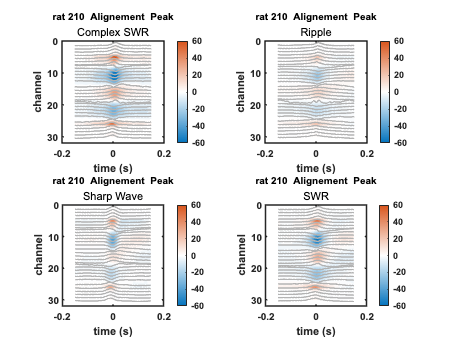

subplot(2,2,1)
contourf(timevect1,1:size(mean_complesSWR,2),mean_complesSWR',40,'LineColor','none');hold on;
colormap(flipud(redblue)); caxis([-cmax1 cmax1]);
colorbar;
clim([-60 60])
set(gca,'YDir','reverse');xlabel('time (s)');ylabel('channel');title('Complex Sharp wave');
% plot([0 0],[1 size(mean_complesSWR,2)],'--k','LineWidth',3);hold on;
% identifying the pyramidal channel 
% yline(pyrLayer,'--b', 'LineWidth',2)
xlim([timeview])
ylim(limYax)
axis square
set(gca,'FontSize',10,'LineWidth',1.5,'FontWeight','bold','FontName','Arial',...
    'PlotBoxAspectRatio',AxisRatioForP)
set(gcf, 'Color','w')
title([ratNum,'Alignement  ',alignementTitle],'Fontsize',10,'Fontweight','bold')
subtitle('Complex SWR')
hold on
for ch=1:size(mean_complesSWR,2)
    sh_tmp = bz_NormToRange(mean_complesSWR(:,ch), [ch+0.5 ch-0.5]);
    plot(timevect1,sh_tmp,'Color',greyColor,'LineWidth',1.5); hold on;
    clear sh_tmp
end
% plot(timevect1,bz_NormToRange(mean_lfp_cSWR(7,:), [4 7]),'k','LineWidth', 2)
% plot(timevect1,bz_NormToRange(mean_lfp_cSWR(10,:), [14 9]),'k','LineWidth', 2)

% print(gcf, '-dpdf', [ratNum,'Alignement  ',alignementTitle,' ComplexRipples']);

% clf;
% figure(2);
subplot(2,2,2)
contourf(timevect1,1:size(mean_Ripple ,2),mean_Ripple',40,'LineColor','none');hold on;
colormap(flipud(redblue)); caxis([-cmax1 cmax1]);
colorbar;
clim([-60 60])
set(gca,'YDir','reverse');xlabel('time (s)');ylabel('channel');title('Ripple');
% plot([0 0],[1 size(mean_Ripple,2)],'--k','LineWidth',3);hold on;
% identifying the pyramidal channel 
% yline(pyrLayer,'--b', 'LineWidth',2)
xlim(timeview)
ylim(limYax)
axis square
set(gca,'FontSize',10,'LineWidth',1.5,'FontWeight','bold','FontName','Arial',...
    'PlotBoxAspectRatio',AxisRatioForP)
set(gcf, 'Color','w')
title([ratNum,'Alignement  ',alignementTitle],'Fontsize',10,'Fontweight','bold')
subtitle('Ripple')
hold on
for ch=1:size(mean_Ripple,2)
    sh_tmp = bz_NormToRange(mean_Ripple(:,ch), [ch+0.5 ch-0.5]);
    plot(timevect1,sh_tmp,'Color',greyColor,'LineWidth',1.5); hold on;
    clear sh_tmp
end
% print(gcf, '-dpdf', [ratNum,'Alignement  ',alignementTitle,' Ripple']);
% print(gcf,'-dpdf','combined figures')
% plot(timevect1,bz_NormToRange(mean_lfp_Ripple(7,:), [4 7]),'k','LineWidth', 2)
% plot(timevect1,bz_NormToRange(mean_lfp_Ripple(10,:), [14 9]),'k','LineWidth', 2)

% clf;
% figure(3);
subplot(2,2,3)
contourf(timevect1,1:size(mean_SW ,2),mean_SW',40,'LineColor','none');hold on;
colormap(flipud(redblue)); caxis([-cmax1 cmax1]);
colorbar;
clim([-60 60])
set(gca,'YDir','reverse');xlabel('time (s)');ylabel('channel');title('Sharp Wave');
% plot([0 0],[1 size(mean_SW,2)],'--k','LineWidth',3);hold on;
% identifying the pyramidal channel 
% yline(pyrLayer,'--b', 'LineWidth',2)
xlim(timeview)
ylim(limYax)
axis square
set(gca,'FontSize',10,'LineWidth',1.5,'FontWeight','bold','FontName','Arial',...
    'PlotBoxAspectRatio',AxisRatioForP)
set(gcf, 'Color','w')
title([ratNum,'Alignement  ',alignementTitle],'Fontsize',10,'Fontweight','bold')
subtitle('Sharp Wave')
hold on
for ch=1:size(mean_SW,2)
    sh_tmp = bz_NormToRange(mean_SW(:,ch), [ch+0.5 ch-0.5]);
    plot(timevect1,sh_tmp,'Color',greyColor,'LineWidth',1.5); hold on;
    clear sh_tmp
end
% print(gcf, '-dpdf', [ratNum,'Alignement  ',alignementTitle,' SW']);
% plot(timevect1,bz_NormToRange(mean_lfp_SW(7,:), [4 7]),'k','LineWidth', 2)
% plot(timevect1,bz_NormToRange(mean_lfp_SW(10,:), [14 9]),'k','LineWidth', 2)

% clf;
% figure(4)
subplot(2,2,4)
contourf(timevect1,1:size(mean_SWR,2),mean_SWR',40,'LineColor','none');hold on;
colormap(flipud(redblue)); caxis([-cmax1 cmax1]);
colorbar;
clim([-60 60])
set(gca,'YDir','reverse');xlabel('time (s)');ylabel('channel');title('Sharp Wave Ripple');
% plot([0 0],[1 size(mean_SWR,2)],'--k','LineWidth',3);hold on;
% identifying the pyramidal channel 
% yline(pyrLayer,'--b', 'LineWidth',2)
xlim(timeview)
ylim(limYax)
axis square
set(gca,'FontSize',10,'LineWidth',1.5,'FontWeight','bold','FontName','Arial',...
    'PlotBoxAspectRatio',AxisRatioForP)
set(gcf, 'Color','w')
title([ratNum,'Alignement  ',alignementTitle],'Fontsize',10,'Fontweight','bold')
subtitle('SWR')
hold on
for ch=1:size(mean_SWR,2)
    sh_tmp = bz_NormToRange(mean_SWR(:,ch), [ch+0.5 ch-0.5]);
    plot(timevect1,sh_tmp,'Color',greyColor,'LineWidth',1.5); hold on;
    clear sh_tmp
end

% plot(timevect1,bz_NormToRange(mean_lfp_SWR(7,:), [4 7]),'k','LineWidth', 2)
% plot(timevect1,bz_NormToRange(mean_lfp_SWR(10,:), [14 9]),'k','LineWidth', 2)

% print(gcf, '-dpdf', [ratNum,'Alignement  ',alignementTitle,' SWR']);
% print(gcf,'-dpdf','combined figures_new')
% export_fig([ratNum,'Alignement  ',alignementTitle,' AllEvent_vehicle_arial'],'-pdf','-transparent','-r300')

In this section I am going to plot individual examples for the paper 

% computing the mean for each condition 
mean_complesSWR     = nanmean(csd_mat_cSWR,3);
mean_Ripple         = nanmean(csd_mat_Ripp,3);
mean_SW             = nanmean(csd_mat_SW,3);
mean_SWR            = nanmean(csd_mat_SWR,3);
% win                 = 1501:2101; % index of the time stamps
cmax1               = max([max(max(mean_complesSWR)) ...
                      max(max(mean_Ripple )) max(max(mean_SW)) max(max(mean_SWR))]);

pyrLayer            = 8;
timeview            = [-0.1 0.1];
ratNum              = 'rat 210  ';
alignementTitle     = 'Peak';
limYax              = [0 32]

limYax =      0    32


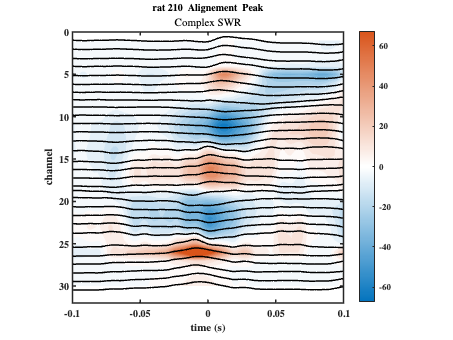


EventNumcSWR        = 3;
EventNumRipp        = 10;
EventNumSW          = 5;
EventNumSWR         = 12;

clf;
figure(1);
contourf(timevect1,1:size(mean_complesSWR,2),csd_mat_cSWR(:,:,EventNumcSWR)',40,'LineColor','none');hold on;
colormap(flipud(redblue)); caxis([-cmax1 cmax1]);
colorbar;
set(gca,'YDir','reverse');xlabel('time (s)');ylabel('channel');title('Complex Sharp wave');
% plot([0 0],[1 size(mean_complesSWR,2)],'--k','LineWidth',3);hold on;
% identifying the pyramidal channel 
% yline(pyrLayer,'--b', 'LineWidth',2)
xlim([timeview])
ylim(limYax)
axis square
set(gca,'FontSize',10,'LineWidth',1.5,'FontWeight','bold','FontName','Times')
set(gcf, 'Color','w')
title([ratNum,'Alignement  ',alignementTitle],'Fontsize',10,'Fontweight','bold')
subtitle('Complex SWR')
hold on
for ch=1:size(mean_complesSWR,2)
    sh_tmp = bz_NormToRange(csd_mat_cSWR(:,ch,EventNumcSWR), [ch+0.5 ch-0.5]);
    plot(timevect1,sh_tmp,'k','LineWidth',1.5); hold on;
    clear sh_tmp
end
print(gcf, '-dpdf', [ratNum,'Alignement  ',alignementTitle,' ComplexRipples SingleEvent Example']);

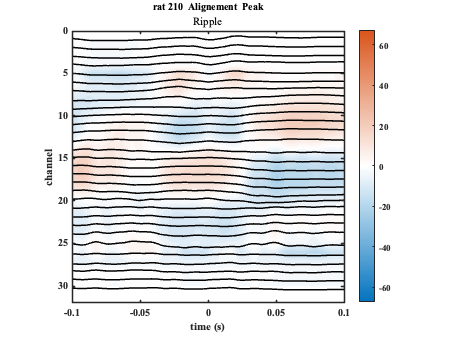



clf;
figure(2);
contourf(timevect2,1:size(mean_Ripple ,2),csd_mat_Ripp(:,:,EventNumRipp)',40,'LineColor','none');hold on;
colormap(flipud(redblue)); caxis([-cmax1 cmax1]);
colorbar;
set(gca,'YDir','reverse');xlabel('time (s)');ylabel('channel');title('Ripple');
% plot([0 0],[1 size(mean_Ripple,2)],'--k','LineWidth',3);hold on;
% identifying the pyramidal channel 
% yline(pyrLayer,'--b', 'LineWidth',2)
xlim(timeview)
ylim(limYax)
axis square
set(gca,'FontSize',10,'LineWidth',1.5,'FontWeight','bold','FontName','Times')
set(gcf, 'Color','w')
title([ratNum,'Alignement  ',alignementTitle],'Fontsize',10,'Fontweight','bold')
subtitle('Ripple')
hold on
for ch=1:size(mean_Ripple,2)
    sh_tmp = bz_NormToRange(csd_mat_Ripp(:,ch,EventNumRipp), [ch+0.5 ch-0.5]);
    plot(timevect2,sh_tmp,'k','LineWidth',1.5); hold on;
    clear sh_tmp
end
print(gcf, '-dpdf', [ratNum,'Alignement  ',alignementTitle,' Ripple SingleEvent Example']);

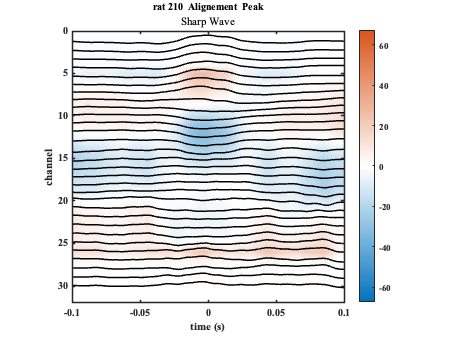




clf;
figure(3);
contourf(timevect2,1:size(mean_SW ,2),csd_mat_SW(:,:,EventNumSW)',40,'LineColor','none');hold on;
colormap(flipud(redblue)); caxis([-cmax1 cmax1]);
colorbar;
set(gca,'YDir','reverse');xlabel('time (s)');ylabel('channel');title('Sharp Wave');
% plot([0 0],[1 size(mean_SW,2)],'--k','LineWidth',3);hold on;
% identifying the pyramidal channel 
% yline(pyrLayer,'--b', 'LineWidth',2)
xlim(timeview)
ylim(limYax)
axis square
set(gca,'FontSize',10,'LineWidth',1.5,'FontWeight','bold','FontName','Times')
set(gcf, 'Color','w')
title([ratNum,'Alignement  ',alignementTitle],'Fontsize',10,'Fontweight','bold')
subtitle('Sharp Wave')
hold on
for ch=1:size(mean_SW,2)
    sh_tmp = bz_NormToRange(csd_mat_SW(:,ch,EventNumSW), [ch+0.5 ch-0.5]);
    plot(timevect3,sh_tmp,'k','LineWidth',1.5); hold on;
    clear sh_tmp
end
print(gcf, '-dpdf', [ratNum,'Alignement  ',alignementTitle,' SW SingleEvent Example']);

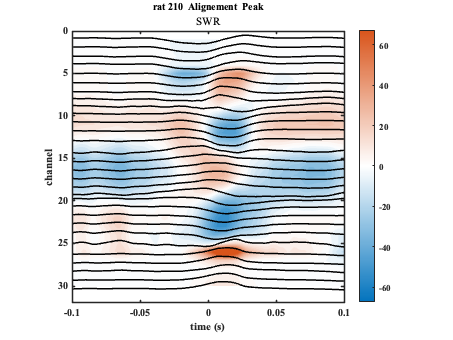



clf;
figure(4)
contourf(timevect3,1:size(mean_SWR,2),csd_mat_SWR(:,:,EventNumSWR)',40,'LineColor','none');hold on;
colormap(flipud(redblue)); caxis([-cmax1 cmax1]);
colorbar;
set(gca,'YDir','reverse');xlabel('time (s)');ylabel('channel');title('Sharp Wave Ripple');
% plot([0 0],[1 size(mean_SWR,2)],'--k','LineWidth',3);hold on;
% identifying the pyramidal channel 
% yline(pyrLayer,'--b', 'LineWidth',2)
xlim(timeview)
ylim(limYax)
axis square
set(gca,'FontSize',10,'LineWidth',1.5,'FontWeight','bold','FontName','Times')
set(gcf, 'Color','w')
title([ratNum,'Alignement  ',alignementTitle],'Fontsize',10,'Fontweight','bold')
subtitle('SWR')
hold on
for ch=1:size(mean_SWR,2)
    sh_tmp = bz_NormToRange(csd_mat_SWR(:,ch,EventNumSWR), [ch+0.5 ch-0.5]);
    plot(timevect2,sh_tmp,'k','LineWidth',1.5); hold on;
    clear sh_tmp
end
print(gcf, '-dpdf', [ratNum,'Alignement  ',alignementTitle,' SWR SingleEvent Example']);

% The aim of this section is to conduct the primary analysis of the CSD signalfollowing El Tabbal Method in his paper: 

% this analysis is a trial to understand the script 
% will choose an example to run the analysis 
% this analysis is based on get_harding function from CoreXplorer
% lab/Magdeburg and the function is coutousy of Deane 2020 
% the link to the function 
% https://github.com/CortXplorer/Deane2020_JPhys/blob/master/Scripts/subfunc/get_Harding.m

% first I choose one example
% one thing that you can do is to 
x               = csd_mat_SWR(:,:,1)';
dim             = 1;

% create shifted matrix x1, where dim 1 is the working dimension
x1              = shiftdim(x,dim-1);
x1dims          = size(x1);

% main computation
x2              = sum(x1);              % computes absolute residues 
x3              = mean(x1);             % computes averaged absolute residues
x4              = x2./sum(abs(x1));     % computes relative residues
x5              = mean(abs(x1));        % computes rectified mean (see Schroeder et al. Cereb Cortex epub ahead of print September 2006)
x6              = x1./repmat(sum(abs(x1)),[size(x1,1),1,1]); % computes relative residues for each channel individually; this enables layer specific analysis
x7              = x1./repmat(x2,[size(x1,1),1,1]); % contribution of channels to the relative residues

% the aim of this section is to compute the AVREC of the signal like El
% Tabbal et al., 
% compute the AVREC for cSWR 
% First--> computing the values for the CA1 only restricted analysis 
channelsCA1                     = [1 19];
ChannelsOr                       = [1 3];
ChannelsPyr                     = [4 7];
ChannelsRad                     = [8 14];
ChannelsMol                     = [15 19];
for icSWR = 1:size(csd_mat_cSWR,3)
    Avrec_cSWR(icSWR,:)         = mean(abs(csd_mat_cSWR(:,channelsCA1(1):channelsCA1(2),icSWR)'));
    RMS_CSWR(icSWR,1)           = rms(Avrec_cSWR(icSWR,:));
    Avrec_cSWR_Or(icSWR,:)      = mean(abs(csd_mat_cSWR(:,ChannelsOr(1):ChannelsOr(2),icSWR)'));
    RMS_cSWR_Or(icSWR,1)        = rms(Avrec_cSWR_Or(icSWR,:));
    Avrec_cSWR_Pyr(icSWR,:)     = mean(abs(csd_mat_cSWR(:,ChannelsPyr(1):ChannelsPyr(2),icSWR)'));
    RMS_cSWR_Pyr(icSWR,1)       = rms(Avrec_cSWR_Pyr(icSWR,:));
    Avrec_cSWR_Rad(icSWR,:)     = mean(abs(csd_mat_cSWR(:,ChannelsRad(1):ChannelsRad(2),icSWR)'));
    RMS_cSWR_Rad(icSWR,1)       = rms(Avrec_cSWR_Rad(icSWR,:));
    Avrec_cSWR_LMo(icSWR,:)     = mean(abs(csd_mat_cSWR(:,ChannelsMol(1):ChannelsMol(2),icSWR)'));
    RMS_cSWR_LMo(icSWR,1)       = rms(Avrec_cSWR_LMo(icSWR,:));
end

for iRipp = 1:size(csd_mat_Ripp,3)
    Avrec_Ripp(iRipp,:)         = mean(abs(csd_mat_Ripp(:,channelsCA1(1):channelsCA1(2),iRipp)'));
    RMS_Ripp(iRipp,1)           = rms(Avrec_Ripp(iRipp,:));
    Avrec_Ripp_Or(iRipp,:)      = mean(abs(csd_mat_Ripp(:,ChannelsOr(1):ChannelsOr(2),iRipp)'));
    RMS_Ripp_Or(iRipp,1)        = rms(Avrec_Ripp_Or(iRipp,:));
    Avrec_Ripp_Pyr(iRipp,:)     = mean(abs(csd_mat_Ripp(:,ChannelsPyr(1):ChannelsPyr(2),iRipp)'));
    RMS_Ripp_Pyr(iRipp,1)       = rms(Avrec_Ripp_Pyr(iRipp,:));
    Avrec_Ripp_Rad(iRipp,:)     = mean(abs(csd_mat_Ripp(:,ChannelsRad(1):ChannelsRad(2),iRipp)'));
    RMS_Ripp_Rad(iRipp,1)       = rms(Avrec_Ripp_Rad(iRipp,:));
    Avrec_Ripp_LMo(iRipp,:)     = mean(abs(csd_mat_Ripp(:,ChannelsMol(1):ChannelsMol(2),iRipp)'));
    RMS_Ripp_LMo(iRipp,1)       = rms(Avrec_Ripp_LMo(iRipp,:));
    
end

for iSW = 1:size(csd_mat_SW,3)
    Avrec_SW(iSW,:)             = mean(abs(csd_mat_SW(:,channelsCA1(1):channelsCA1(2),iSW)'));
    RMS_SW(iSW,:)               = rms(Avrec_SW(iSW,:));
    Avrec_SW_Or(iSW,:)          = mean(abs(csd_mat_SW(:,ChannelsOr(1):ChannelsOr(2),iSW)'));
    RMS_SW_Or(iSW,1)            = rms(Avrec_SW_Or(iSW,:));
    Avrec_SW_Pyr(iSW,:)         = mean(abs(csd_mat_SW(:,ChannelsPyr(1):ChannelsPyr(2),iSW)'));
    RMS_SW_Pyr(iSW,1)           = rms(Avrec_SW_Pyr(iSW,:));
    Avrec_SW_Rad(iSW,:)         = mean(abs(csd_mat_SW(:,ChannelsRad(1):ChannelsRad(2),iSW)'));
    RMS_SW_Rad(iSW,1)           = rms(Avrec_SW_Rad(iSW,:));
    Avrec_SW_LMo(iSW,:)         = mean(abs(csd_mat_SW(:,ChannelsMol(1):ChannelsMol(2),iSW)'));
    RMS_SW_LMo(iSW,1)           = rms(Avrec_SW_LMo(iSW,:));
end

for iSWR = 1:size(csd_mat_SWR,3)
    Avrec_SWR(iSWR,:)           = mean(abs(csd_mat_SWR(:,channelsCA1(1):channelsCA1(2),iSWR)'));
    RMS_SWR(iSWR,:)             = rms(Avrec_SWR(iSWR,:));
    Avrec_SWR_Or(iSWR,:)        = mean(abs(csd_mat_SWR(:,ChannelsOr(1):ChannelsOr(2),iSWR)'));
    RMS_SWR_Or(iSWR,1)          = rms(Avrec_SWR_Or(iSWR,:));
    Avrec_SWR_Pyr(iSWR,:)       = mean(abs(csd_mat_SWR(:,ChannelsPyr(1):ChannelsPyr(2),iSWR)'));
    RMS_SWR_Pyr(iSWR,1)         = rms(Avrec_SWR_Pyr(iSWR,:));
    Avrec_SWR_Rad(iSWR,:)       = mean(abs(csd_mat_SWR(:,ChannelsRad(1):ChannelsRad(2),iSWR)'));
    RMS_SWR_Rad(iSWR,1)         = rms(Avrec_SWR_Rad(iSWR,:));
    Avrec_SWR_LMo(iSWR,:)       = mean(abs(csd_mat_SWR(:,ChannelsMol(1):ChannelsMol(2),iSWR)'));
    RMS_SWR_LMo(iSWR,1)         = rms(Avrec_SWR_LMo(iSWR,:));
end

% computing the mean and the standard deviation of each state for plotting 
Avrec_sem_cSWR                  = std(Avrec_cSWR) / sqrt(size(Avrec_cSWR,1));
Avrec_sem_Ripp                  = std(Avrec_Ripp) / sqrt(size(Avrec_Ripp,1));
Avrec_sem_SW                    = std(Avrec_SW) / sqrt(size(Avrec_SW,1));
Avrec_sem_SWR                   = std(Avrec_SWR) / sqrt(size(Avrec_SWR,1));


% stratum radiatum
Avrect_sem_cSWR_Rad             = std(Avrec_cSWR_Rad) / sqrt(size(Avrec_cSWR_Rad,1));
disp('Finished AVREC computations...')

Finished AVREC computations...


% parameters that are important for plotting the results 
pyrLayer            = 8;
timeview            = [-0.2 0.2];
ratNum              = 'rat 210  ';
alignementTitle     = 'Peak';
limYax              = [0 32]

limYax =      0    32



EventNumcSWR        = 3;
EventNumRipp        = 10;
EventNumSW          = 5;
EventNumSWR         = 12;

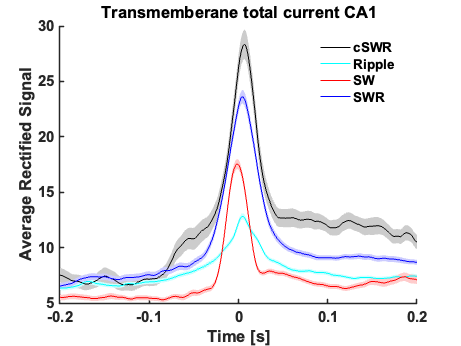

% making a nice plot 
figure;
boundedline(timevect3,mean(Avrec_cSWR),Avrec_sem_cSWR ,'k',...
    timevect3,mean(Avrec_Ripp), Avrec_sem_Ripp,'c',...
    timevect3,mean(Avrec_SW), Avrec_sem_SW,'r', ...
    timevect3,mean(Avrec_SWR),Avrec_sem_SWR,'b')
legend('','','','','cSWR','Ripple','SW','SWR','Location','best')
legend boxoff

xlabel('Time [s]')
xlim(timeview)
ylabel('Average Rectified Signal')
set(gca,'FontSize',15,'LineWidth',1.5,'FontWeight','bold','FontName','Arial')
title('Transmemberane total current CA1')
set(gcf,'Color','w')
FigTitleAVREC = [ratNum, 'Alignment ', alignementTitle,' CA1_all_layers_aVREC.pdf'];
% export_fig([ratNum,'Alignement  ',alignementTitle,' CA1_AVREC_allLayers'],'-pdf','-transparent','-r300')
exportgraphics(gcf,FigTitleAVREC,'BackgroundColor','none','ContentType','vector','Resolution',300)

% computing the RMS value for each event type and plotting it 
KLAll = [RMS_CSWR' RMS_Ripp' RMS_SW' RMS_SWR'];
grp = [zeros(1,length(RMS_CSWR)), ones(1,length(RMS_Ripp)),ones(1,length(RMS_SW))*2,...
    ones(1,length(RMS_SWR))*3];
figure
h = boxplot(KLAll,grp,'symbol','o','Labels',{'cSWR','Ripp','SW','SWR'},...
    'Widths',0.5)

h =   234.0001  241.0001  248.0001  255.0001
  235.0001  242.0001  249.0001  256.0001
  236.0001  243.0001  250.0001  257.0001
  237.0001  244.0001  251.0001  258.0001
  238.0001  245.0001  252.0001  259.0001
  239.0001  246.0001  253.0001  260.0001
  240.0001  247.0001  254.0001  261.0001


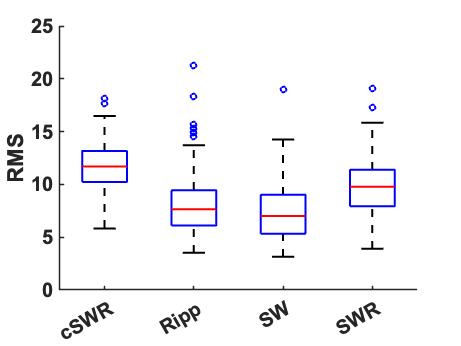

xtickangle(30)
set(h,{'linew'},{2})
ylabel('RMS')
ylim([0 25])
set(gca,'FontSize',20,'LineWidth',1.5,'FontWeight','bold','FontName','Arial')
box off
set(gcf,'Color','w')
% print(gcf, '-dpdf', 'ThetaPowerComparison.pdf');
FigTitleRMs = [ratNum, 'Alignment ', alignementTitle,' CA1_all_layers_RMS.pdf'];
% export_fig(FigTitleRMs ,'-pdf','-transparent','r-300')
exportgraphics(gcf,FigTitleRMs,'BackgroundColor','none','ContentType','vector','Resolution',300)

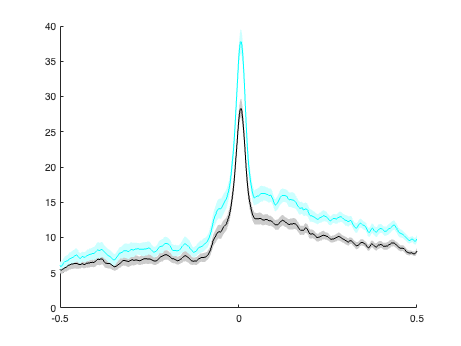

% computing the average per layer
figure
boundedline(timevect3,mean(Avrec_cSWR),Avrec_sem_cSWR ,'k',...
    timevect3,mean(Avrec_cSWR_Rad), Avrect_sem_cSWR_Rad,'c')

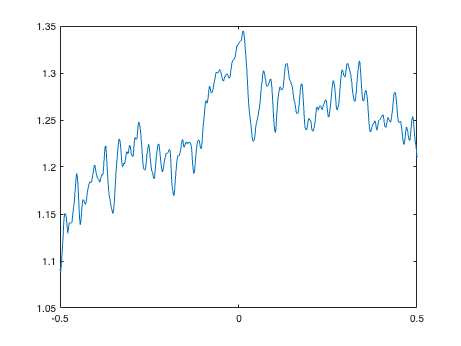

figure
plot(timevect3, mean(Avrec_cSWR_Rad) ./ mean(Avrec_cSWR))

% writing the data in table
sizeofAllData = size(Avrec_cSWR,1) + size(Avrec_cSWR_Or,1) + size(Avrec_cSWR_Pyr,1) + size(Avrec_cSWR_Rad,1);
clear T_cSWR_all T_cSWR_OR
T_cSWR_all      = table(repmat('210', size(Avrec_cSWR,1),1), repmat('veh',size(Avrec_cSWR,1),1),...
    repmat('all', size(Avrec_cSWR,1),1),repmat('cSWR',size(Avrec_cSWR,1),1),...
    repmat('Peak', size(Avrec_cSWR,1),1),Avrec_cSWR);

Error using table
All table variables must have the same number of
rows.

T_cSWR_OR       = table(repmat('210', size(Avrec_cSWR,1),1), repmat('veh',size(Avrec_cSWR,1),1),...
    repmat('OR', size(Avrec_cSWR,1),1),repmat('cSWR',size(Avrec_cSWR,1),1),...
    repmat('Peak', size(Avrec_cSWR,1),1),Avrec_cSWR_Or);
T_cSWR_Pyr      = table(repmat('210', size(Avrec_cSWR,1),1), repmat('veh',size(Avrec_cSWR,1),1),...
    repmat('Pyr', size(Avrec_cSWR,1),1),repmat('cSWR',size(Avrec_cSWR,1),1),...
    repmat('Peak', size(Avrec_cSWR,1),1),Avrec_cSWR_Pyr);
T_cSWR_Rad      = table(repmat('210', size(Avrec_cSWR,1),1), repmat('veh',size(Avrec_cSWR,1),1),...
    repmat('Rad', size(Avrec_cSWR,1),1),repmat('cSWR',size(Avrec_cSWR,1),1),...
    repmat('Peak', size(Avrec_cSWR,1),1),Avrec_cSWR_Rad);
T_cSWR_Lmo      = table(repmat('210', size(Avrec_cSWR,1),1), repmat('veh',size(Avrec_cSWR,1),1),...
    repmat('Lmo', size(Avrec_cSWR,1),1),repmat('cSWR',size(Avrec_cSWR,1),1),...
    repmat('Peak', size(Avrec_cSWR,1),1),Avrec_cSWR_LMo);

% second table 
clear T_cSWR_all T_cSWR_OR T_cSWR_Pyr T_cSWR_Rad T_cSWR_Lmo
sizeVar = size(Avrec_SWR,1);
TypeName = 'SWR';
T_cSWR_all      = table(repmat('210', sizeVar,1), repmat('veh',sizeVar,1),...
    repmat('all', sizeVar,1),repmat(TypeName,sizeVar,1),...
    repmat('Peak', sizeVar,1),Avrec_SWR);


T_cSWR_OR       = table(repmat('210', sizeVar,1), repmat('veh',sizeVar,1),...
    repmat('OR', sizeVar,1),repmat(TypeName,sizeVar,1),...
    repmat('Peak', sizeVar,1),Avrec_SWR_Or);


T_cSWR_Pyr      = table(repmat('210', sizeVar,1), repmat('veh',sizeVar,1),...
    repmat('Pyr', sizeVar,1),repmat(TypeName,sizeVar,1),...
    repmat('Peak', sizeVar,1),Avrec_SWR_Pyr);


T_cSWR_Rad      = table(repmat('210', sizeVar,1), repmat('veh',sizeVar,1),...
    repmat('Rad', sizeVar,1),repmat(TypeName,sizeVar,1),...
    repmat('Peak', sizeVar,1),Avrec_SWR_Rad);


T_cSWR_Lmo      = table(repmat('210', sizeVar,1), repmat('veh',sizeVar,1),...
    repmat('Lmo', sizeVar,1),repmat(TypeName,sizeVar,1),...
    repmat('Peak', sizeVar,1),Avrec_SWR_LMo);

% table for RMS values 
clear T_cSWR_all T_cSWR_OR T_cSWR_Pyr T_cSWR_Rad T_cSWR_Lmo
sizeVar = size(RMS_SWR,1);
TypeName = 'SWR'; %'cSWR', 'Ripp', 'SW', 'SWR'


T_cSWR_all      = table(repmat('210', sizeVar,1), repmat('veh',sizeVar,1),...
    repmat('all', sizeVar,1),repmat(TypeName,sizeVar,1),...
    repmat('Peak', sizeVar,1),RMS_SWR);


T_cSWR_OR       = table(repmat('210', sizeVar,1), repmat('veh',sizeVar,1),...
    repmat('OR', sizeVar,1),repmat(TypeName,sizeVar,1),...
    repmat('Peak', sizeVar,1),RMS_SWR_Or);


T_cSWR_Pyr      = table(repmat('210', sizeVar,1), repmat('veh',sizeVar,1),...
    repmat('Pyr', sizeVar,1),repmat(TypeName,sizeVar,1),...
    repmat('Peak', sizeVar,1),RMS_SWR_Pyr);


T_cSWR_Rad      = table(repmat('210', sizeVar,1), repmat('veh',sizeVar,1),...
    repmat('Rad', sizeVar,1),repmat(TypeName,sizeVar,1),...
    repmat('Peak', sizeVar,1),RMS_SWR_Rad);


T_cSWR_Lmo      = table(repmat('210', sizeVar,1), repmat('veh',sizeVar,1),...
    repmat('Lmo', sizeVar,1),repmat(TypeName,sizeVar,1),...
    repmat('Peak', sizeVar,1),RMS_SWR_LMo);